**AVD Group 01**

Hanchen Li

Note that all the **units** in equation are** imperial**

% House Keeping
clear
clc
close all

g = 9.80665;                          % Standard acceleration of gravity (m/s^2)

## **1. Weight Estimation**

### **1.1 Structures Group**

**Aircraft Wings**

% Basic Parameters

W_dg = 4.2990e5;                      % Design gross weight (kg)
W_dg = convmass(W_dg, 'kg', 'lbm');   % Design gross weight (lb)

N_z = 1.5 * 2.5;                      % Ultimate load factor (1.5 x limit load factor)

S_w = 639.23;                         % Reference wing area (m^2)
S_w = convlength(S_w, 'm', 'ft');  
S_w = convlength(S_w, 'm', 'ft');     % Reference wing area (ft^2)

AR = 6.61;                            % Aspect Ratio

Taper = 0.20;                         % Wing taper ratio % Undefined

S_cs = 199;                           % Total control surface area (m^2) % Undefined
S_cs = convlength(S_cs, 'm', 'ft');  
S_cs = convlength(S_cs, 'm', 'ft');   % Total control surface area (ft^2)

S_csw = 120;                          % Area of wing mounted control surfaces (m^2) % Undefined
S_csw = convlength(S_csw, 'm', 'ft');  
S_csw = convlength(S_csw, 'm', 'ft'); % Area of wing mounted control surfaces (ft^2)

Sweep = 26.75;                        % Wing quarter chord sweep (degree) % Undefined
Sweep = deg2rad(Sweep);               % Wing quarter chord sweep (rad)

t_c_root = 0.1401;                    % Wing root thickness to chord ratio % Undefined

B_w = 64.99;                          % Wing span (m)
B_w = convlength(B_w, 'm', 'ft');     % Wing span (ft)

L_D = 14.73;                          % Lift to drag ratio (at cruise?)

V_S = 50.34;                          % Landing stall speed (m/s) % Undefined
V_S = convvel(V_S, 'm/s', 'ft/s');    % Landing stall speed (ft/s)

% Calculation

W_w = 0.0051 * (((W_dg * N_z) ^ 0.557) * (S_w ^ 0.649) * (AR ^ 0.5) * ((1 + Taper) ^ 0.1) * (S_csw ^ 0.1)) ...
    / (cos(Sweep) * (t_c_root ^ 0.4));

W_w = convmass(W_w, 'lbm', 'kg')

W_w = 4.2008e+04


% Use advanced composites

W_w = 0.78 * W_w

W_w = 3.2766e+04


W_w = 32985

W_w = 32985

**Horizontal Tailplane**

% Basic Parameters

K_uht = 1.0;                          % 1.143 for all-moving tail % 1.0 otherwise

S_ht = 87.2;                          % Horizontal tailplane area (m^2) % Undefined
S_ht = convlength(S_ht, 'm', 'ft');  
S_ht = convlength(S_ht, 'm', 'ft');   % Horizontal tailplane area (ft^2)

L_ht = 33.4;                          % Length from wing AC to horizontal tailplane AC (m) % Undefined
L_ht = convlength(L_ht, 'm', 'ft');   % Length from wing AC to horizontal tailplane AC (ft)
K_y = 0.3 * L_ht;                     % Aircraft pitching radius of gyration

AR_h = 8;                             % Horizontal tailplane aspect Ratio

S_e = 55;                             % Elevator area (m^2)
S_e = convlength(S_e, 'm', 'ft');  
S_e = convlength(S_e, 'm', 'ft');     % Elevator area (ft^2)

F_w = 5;                              % Fuselage width at horizontal tail intersection (m)
F_w = convlength(F_w, 'm', 'ft');     % Fuselage width at horizontal tail intersection (ft)

B_ht = 32;                            % Horizontal tailplane span (m)
B_ht = convlength(B_ht, 'm', 'ft');   % Horizontal tailplane span (ft)

Sweep_ht = 23;                        % Horizontal tailplane quarter chord sweep (degree) % Undefined
Sweep_ht = deg2rad(Sweep_ht);         % Horizontal tailplane quarter chord sweep (rad)

% Calculation

W_ht = 0.0379 * (K_uht * (W_dg ^ 0.639) * (N_z ^ 0.1) * (S_ht ^ 0.75) * (K_y ^ 0.704) * (AR_h ^ 0.166) ...
    * (1 + S_e / S_ht) ^ 0.1) / ((1 + F_w / B_ht) ^ 0.25 * L_ht * cos(Sweep_ht));

W_ht = convmass(W_ht, 'lbm', 'kg')

W_ht = 3.6365e+03


% Use advanced composites

W_ht = 0.75 * W_ht

W_ht = 2.7274e+03

**Vertical Tailplane**

% Basic Parameters

H_t_v = 0;                            % 0 for fuselage mounted horizontal % 1.0 for T-tail

S_vt = 63.4;                          % Vertical tailplane area (m^2) % Undefined
S_vt = convlength(S_vt, 'm', 'ft');  
S_vt = convlength(S_vt, 'm', 'ft');   % Vertical tailplane area (ft^2)

L_vt = 32.3;                          % Length from wing AC to vertical tailplane AC (m) % Undefined
L_vt = convlength(L_vt, 'm', 'ft');   % Length from wing AC to vertical tailplane AC (ft)
K_z = L_vt;                           % Aircraft yaw radius of gyration

AR_v = 1.8;                           % Vertical tailplane aspect Ratio

Sweep_vt = 35;                        % Vertical tailplane quarter chord sweep (degree) % Undefined
Sweep_vt = deg2rad(Sweep_vt);         % Vertical tailplane quarter chord sweep (rad)

t_c_root_v = 0.13;                    % Vertical tailplane root thickness to chord ratio % Undefined

% Calculation

W_vt = 0.0026 * (((1 + H_t_v) ^ 0.225) * (W_dg ^ 0.556) * (N_z ^ 0.536) * (S_vt ^ 0.5) * (K_z ^ 0.875) ...
    * (AR_v ^ 0.35)) / ((L_vt ^ 0.5) * cos(Sweep_vt) * (t_c_root_v ^ 0.5));

W_vt = convmass(W_vt, 'lbm', 'kg')

W_vt = 3.1467e+03


% Use advanced composites

W_vt = 0.75 * W_vt

W_vt = 2.3600e+03

**Fuselage**

% Basic Parameters

K_door = 1.06;                        % Undefined                       
% 1.0 if no cargo door, 1.06 for one side cargo door % 1.12 for two side cargo doors
% 1.12 for aft clamshell door, 1.25 for two side and an aft clamshell cargo doors

K_Lg = 1.0;                           % 1.12 for fuselage mounted landing gear % 1.0 otherwise

S_f = 1263.5;                         % Fuselage wetted area (m^2) % Undefined

L_f = 75.5;                           % Total fuselage length (m) % Undefined
L_f = convlength(L_f, 'm', 'ft');     % Total fuselage length (ft)

L = 72;                               % Fuselage structual length (m) % Undefined
L = convlength(L, 'm', 'ft');         % Fuselage structual length (ft)

K_ws = 0.75 * ((1 + 2 * Taper) / (1 + Taper)) * B_w * tan(Taper) / L

K_ws = 0.1601


% Calculation

W_fus = 0.3280 * K_door * K_Lg * ((W_dg * N_z) ^ 0.5) * (L ^ 0.25) * (S_f ^ 0.302) ...
    * ((1 + K_ws) ^ 0.04) * (L_D ^ 0.1);

W_fus = convmass(W_fus, 'lbm', 'kg')

W_fus = 1.3262e+04


% Use advanced composites

W_fus = 0.85 * W_fus

W_fus = 1.1273e+04

**Main Landing Gear**

% Basic Parameters

K_mp = 1.0;                           % 1.126 for kneeling main gear % 1.0 otherwise

W_l = 0.9 * W_dg;                     % Landing design gross weight (lb) % Need clarify

N_gear = 3;                           % Undefined                 
% Ratio of average total load applied to the main gear during landing to the max landing weight
% Typically 2.7-3 for commercial aircraft

N_l = 1.5 * N_gear;                   % Ultimate landing gear load factor

L_m = 4.45;                           % Main landing gear length (m) % Undefined 
L_m = convlength(L_m, 'm', 'in');     % Main landing gear length (inches)

N_mw = 12;                            % Number of main wheels % Undefined

N_mss = 2;                            % Number of main gear shock struts % Undefined

% Calculation

W_mlg = 0.0106 * K_mp * (W_l ^ 0.888) * (N_l ^ 0.25) * (L_m ^ 0.4) * (N_mw ^ 0.321) ...
    * (V_S ^ 0.1) / (N_mss ^ 0.5);

W_mlg = convmass(W_mlg, 'lbm', 'kg')

W_mlg = 2.6733e+04


% Use advanced composites

% W_mlg = 0.88 * W_mlg

**Nose Landing Gear**

% Basic Parameters

K_np = 1.0;                           % 1.15 for kneeling nose-gear % 1.0 otherwise

L_n = 4.45;                           % Nose landing gear length (m) % Undefined 
L_n = convlength(L_n, 'm', 'in');     % Nose landing gear length (inches)

N_nw = 2;                             % Number of nose wheels % Undefined

% Calculation

W_nlg = 0.032 * K_np * (W_l ^ 0.646) * (N_l ^ 0.2) * (L_n ^ 0.5) * (N_nw ^ 0.45);

W_nlg = convmass(W_nlg, 'lbm', 'kg')

W_nlg = 2.4048e+03


% Use advanced composites

% W_nlg = 0.88 * W_nlg

### **1.2 Propulsion Group**

**Engine with Nacelle**

% Basic Parameters

N_en = 4;                             % Number of engines

W_en = 6125;                          % Engine dry weight (kg)
W_en = convmass(W_en, 'kg', 'lbm');   % Engine dry weight (lb)

% Calculatin

W_enc = 2.331 * 1 * 1.18 * W_en ^ 0.901;

convmass(W_enc,'lbm','kg')

ans = 6.5708e+03


W_enc_total = N_en * convmass(W_enc, 'lbm', 'kg')

W_enc_total = 2.6283e+04

**Naclle**

% Basic Parameters

% K_ng = 1.017;                         % 1.017 for pylon mounted nacelle % 1.0 otherwise % Undefined 

% N_Lt = 5.3;                           % Naclle length (m) % Undefined 
% N_Lt = convlength(N_Lt, 'm', 'ft');   % Naclle length (ft)

% N_w = 3;                              % Naclle width (m) % Undefined 
% N_w = convlength(N_w, 'm', 'ft');     % Naclle width (ft)

% S_n = 27;                             % Nacelle wetted area (m^2)
% S_n = convlength(S_n, 'm', 'ft');  
% S_n = convlength(S_n, 'm', 'ft');     % Nacelle wetted area (ft^2)

% Calculation

% W_inl = 0.6724 * K_ng * (N_Lt ^ 0.1) * (N_w ^ 0.294) * (N_z ^ 0.119) * (W_enc ^ 0.611) * (N_en ^ 0.984) * (S_n ^ 0.224);

% W_inl = convmass(W_inl, 'lbm', 'kg')

% Use advanced composites

% W_inl = 0.85 * W_inl

**Engine Controls**

% Basic Parameters

L_ec = 55;
% Total engine controls routing distance, engine to cockpit (m) 
L_ec = convlength(L_ec, 'm', 'ft');   % Total engine controls routing distance (ft)

% Calculation

W_ec = 5 * N_en + 0.8 * L_ec;

W_ec = convmass(W_ec, 'lbm', 'kg')

W_ec = 74.5511

**Engine (Pneumatic) Starter**

% Calculation

W_es = 49.19 * (N_en * W_en / 1e3) ^ 0.541;

W_es = convmass(W_es, 'lbm', 'kg')

W_es = 193.1191

**Fuel System**

% Basic Parameters

V_t = 282;                            % Total volume of fuel tanks (m^3) % Undefined 
V_t = V_t / 0.0037854118;             % Total volume of fuel tanks (gal)

N_t = 8;                             % Total number of fuel tanks % Undefined

V_p = 0;                              % Self sealing tank volume (m^3) % Undefined 
V_p = V_p / 0.0037854118;             % Self sealing tank volume (gal)

V_i = 280;                            % Integral fuel tank volume (m^3) % Undefined 
V_i = V_i / 0.0037854118;             % Integral fuel tank volume (gal)

% Calculation

W_fs = 2.405 * (V_t ^ 0.606) * (N_t ^ 0.5) * ((1 + V_p / V_t) / (1 + V_i / V_t));

W_fs = convmass(W_fs, 'lbm', 'kg')

W_fs = 1.3879e+03

### **1.3 Equipment Group**

**Flight Controls**

% Basic Parameters

N_f = 6;                              % Undefined
% Number of function performed by controls % Typically 4-7

N_m = 1;                              % Undefined
% Number of mechanical function performed by controls % Typically 0-2

% I_y = W_fc * (K_y ^ 2) / g;

% Calculation

syms Wfc

assume(Wfc > 0)

W_fc = double(solve(145.9 * ((N_f ^ 0.554) * (S_cs ^ 0.2) * (((Wfc * (K_y ^ 2) / g) * 1e-6) ^ 0.07)) / (1 + N_m / N_f) == Wfc, Wfc));

W_fc = convmass(W_fc, 'lbm', 'kg')

W_fc = 621.6858

clearvars Wfc

**Installed APU**

% Basic Parameters

W_APU = 425;                          % Uninstalled APU weight (kg) % Undefined
W_APU = convmass(W_APU, 'kg', 'lbm'); % Uninstalled APU weight (lb)

% Calculation

W_APUinst = 2.2 * W_APU;

W_APUinst = convmass(W_APUinst, 'lbm', 'kg')

W_APUinst = 935.0000

**Instruments**

% Basic Parameters

K_r = 1.0;                            % 1.133 for reciprocatiing engines % 1.0 otherwise

K_tp = 1.0;                           % 0.793 for turboprop % 1.0 otherwise

N_c = 4;                              % Number of crew

% Calculation

W_instr = 4.509 * K_r * K_tp * (N_c ^ 0.541) * N_en * ((L_f + B_w) ^ 0.5);

W_instr = convmass(W_instr, 'lbm', 'kg')

W_instr = 371.8225

**Hydraulic System**

% Calculation

W_hydr = 0.2673 * N_f * ((L_f + B_w) ^ 0.937);

W_hydr = convmass(W_hydr, 'lbm', 'kg')

W_hydr = 227.8440

**Electrical System**

% Basic Parameters

R_kva = 120;                          % Undefined
% System electrical rating (kVA) % typically 40-60 for transports

L_a = 55;                             % Undefined
% Electrical routing distance, generators to avionics to cockpit (m)
L_a = convlength(L_a, 'm', 'ft');     % Electrical routing distance (ft)

N_gen = N_en + 1;                     % Number of generators % typically = N_en

% Calculation

W_el = 7.291 * (R_kva ^ 0.782) * (L_a ^ 0.346) * (N_gen ^ 0.1);

W_el = convmass(W_el, 'lbm', 'kg')

W_el = 990.7541

**Avionics**

% Basic Parameters

W_uav = 1300;                         % Undefined
% Uninstalled avionics weight (kg) % typically 800-1400 lb (363-635 kg)
W_uav = convmass(W_uav, 'kg', 'lbm'); % Uninstalled avionics weight (lb)

% Calculation

W_av = 1.73 * W_uav ^ 0.983;

W_av = convmass(W_av, 'lbm', 'kg')

W_av = 1.9643e+03

**Furnishings**

% Basic Parameters

W_c = 500 * 17 + (12 + 4) * 13.6      % Maximum cargo weight (kg)

W_c = 8.7176e+03

W_c = convmass(W_c, 'kg', 'lbm');     % Maximum cargo weight (lb)

N_seat_eco = 430;                     % Number of economic seats
W_seat_eco = 20;                      % Weight of a single economic seat (kg)
W_seat_eco = convmass(W_seat_eco, 'kg', 'lbm'); 
% Weight of single economic seat (lb)

N_seat_busi = 70;                     % Number of business seats
W_seat_busi = 60;                     % Weight of a single business seat (kg)
W_seat_busi = convmass(W_seat_busi, 'kg', 'lbm'); 
% Weight of single business seat (lb)

N_seat_jump = 12;                     % Number of jump seats
W_seat_jump = 15;                     % Weight of a single jump seat (kg)
W_seat_jump = convmass(W_seat_jump, 'kg', 'lbm'); 
% Weight of single jump seat (lb)

K_lav = 1.11;
% 1.11 for long range aircraft % 0.31 for short range aircraft
% 3.9 for business jet

K_buf = 5.68;
% 1.02 for short range % 5.68 for very long range

N_p = 500 + 12 + 4;                   % Total number of person onboard

% Calculation

W_furn = 0.0577 * (N_c ^ 0.1) * (W_c ^ 0.393) * (S_f ^ 0.75) + ...
    N_seat_eco * W_seat_eco + N_seat_busi * W_seat_busi + N_seat_jump * W_seat_jump + ...
    K_lav * (N_p ^ 1.33) + K_buf * (N_p ^ 1.12);

W_furn = convmass(W_furn, 'lbm', 'kg')

W_furn = 1.8141e+04

**Air-Conditioning**

% Basic Parameters

V_pr = 1160;                            % Volume of pressurized sections (m^3) % Undefined
V_pr = convlength(V_pr, 'm', 'ft');
V_pr = convlength(V_pr, 'm', 'ft');
V_pr = convlength(V_pr, 'm', 'ft');   % Volume of pressurized sections (ft^3)

% Calculation

W_ac = 62.36 * (N_p ^ 0.25) * ((V_pr * 1e-3) ^ 0.604) ^ (W_uav ^ 0.1);

W_ac = convmass(W_ac, 'lbm', 'kg')

W_ac = 1.9439e+04

**Anti-Icing System**

% Calculation

W_ai = 0.002 * W_dg;

W_ai = convmass(W_ai, 'lbm', 'kg')

W_ai = 859.8000

**Handling Gear**

% Calculation

W_hg = 3e-4 * W_dg;

W_hg = convmass(W_hg, 'lbm', 'kg')

W_hg = 128.9700


% Not included

W_hg = 0

W_hg = 0

### **1.4 Overall**

**Gross Weight**

% Calculation

W_0 = convmass(W_dg, 'lbm', 'kg')

W_0 = 429900

**Crew Weight**

% Calculation

W_crew = 500 * 82.8 + (12 + 4) * 79.4

W_crew = 4.2670e+04

**Payload Weight**

% Calculation

W_payload = convmass(W_c, 'lbm', 'kg')

W_payload = 8.7176e+03

**Empty Weight**

% Calculation

W_e = W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + W_enc_total + W_ec + W_es + W_fs + W_fc + ...
    W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg

W_e = 1.4997e+05


% Add 5% allowence
W_e = 1.05 * W_e % 3-10% at this point

W_e = 1.5747e+05

% Design empty weight is 181910 kg

**Fuel Weight**

% Calculation

W_f = W_0 - W_e - W_crew - W_payload

W_f = 2.2104e+05

% Design fuel weight is 196600 kg

### **1.5 Fuel Tanks (and Water Tank?)**

**Inner Wing Fuel Tanks**

W_f_in = 2 * 50000 % (kg)

W_f_in = 100000

**Outer Wing Fuel Tanks**

W_f_out = 2 * 15000 % (kg)

W_f_out = 30000

**Center Wing Fuel Tank**

W_f_centre = 66000 % (kg)

W_f_centre = 66000

**Trim Tank**

W_f_trim = 2 * 2000 % (kg)

W_f_trim = 4000

**Surge Tank**

W_f_surge = 10000 % (kg)

W_f_surge = 10000

**Water Tank**

**Check if fuel weight fit**

W_excess = W_f_in + W_f_out + W_f_centre - W_f

W_excess = -2.5039e+04


if W_excess >= 0

else

    fprintf('Fuel tank capacity is not enough for take-off fuel weight')

    W_f_centre = W_f_centre - W_excess;

    W_f_centre = 1.1 * W_f_centre

end

Fuel tank capacity is not enough for take-off fuel weight

W_f_centre = 1.0014e+05

## **2. CG Estimation**

### **2.1 Structures Group**

**Aircraft Wings**

x_w_l = 33.2

x_w_l = 33.2000

x_w = x_w_l + 3.4

x_w = 36.6000

z_w = -1.5

z_w = -1.5000

**Horizontal Tailplane**

x_ht = 70

x_ht = 70

z_ht = 1

z_ht = 1

**Vertical Tailplane**

x_vt = 68

x_vt = 68

z_vt = 5.5

z_vt = 5.5000

**Fuselage**

x_fus = 34.15

x_fus = 34.1500

z_fus = 0

z_fus = 0

**Main Landing Gear (Down)**

x_mlg_down = 38.18

x_mlg_down = 38.1800

z_mlg_down = -7.93

z_mlg_down = -7.9300

**Main Landing Gear (Up)**

x_mlg_up = 37.60

x_mlg_up = 37.6000

z_mlg_up = -1.60

z_mlg_up = -1.6000

**Nose Landing Gear (Down)**

x_nlg_down = 6.70

x_nlg_down = 6.7000

z_nlg_down = -7.93

z_nlg_down = -7.9300

**Nose Landing Gear (Up)**

x_nlg_up = 11.46

x_nlg_up = 11.4600

z_nlg_up = -1.50

z_nlg_up = -1.5000

### **2.2 Propulsion Group**

**Engine with Nacelle**

x_enc = x_w_l - 3.6

x_enc = 29.6000

z_enc = -2.5

z_enc = -2.5000

**Naclle**

%

**Engine Controls**

x_ec = x_w_l - 3

x_ec = 30.2000

z_ec = -4.0

z_ec = -4

**Engine (Pneumatic) Starter**

x_es = x_w_l - 3

x_es = 30.2000

z_es = -4

z_es = -4

**Fuel System**

x_fs = x_w_l - 3

x_fs = 30.2000

z_fs = -1

z_fs = -1

### **2.3 Equipment Group**

**Flight Controls**

x_fc = 36.6

x_fc = 36.6000

z_fc = 0

z_fc = 0

**Installed APU**

x_APUinst = 69

x_APUinst = 69

z_APUinst = 1.4

z_APUinst = 1.4000

**Instruments**

x_instr = 2.3

x_instr = 2.3000

z_instr = 1.2

z_instr = 1.2000

**Hydraulic System**

x_hydr = 33

x_hydr = 33

z_hydr = 0.4

z_hydr = 0.4000

**Electrical System**

x_el = 31

x_el = 31

z_el = 2.4

z_el = 2.4000

**Avionics**

x_av = 2.3

x_av = 2.3000

z_av = -0.10

z_av = -0.1000

**Furnishings**

x_furn = 30.5

x_furn = 30.5000

z_furn = 0.5

z_furn = 0.5000

**Air-Conditioning**

x_ac = 37.5

x_ac = 37.5000

z_ac = 2.7

z_ac = 2.7000

**Anti-Icing System**

x_ai = 39.4

x_ai = 39.4000

z_ai = 0

z_ai = 0

**Handling Gear**

x_hg = 0

x_hg = 0

z_hg = 0

z_hg = 0

### **2.4 Fuel Tanks**

**Inner Wing Fuel Tanks**

x_f_in = x_w_l + 10

x_f_in = 43.2000

z_f_in = 0

z_f_in = 0

**Outer Wing Fuel Tanks**

x_f_out = x_w_l + 14

x_f_out = 47.2000

z_f_out = 0.50

z_f_out = 0.5000

**Center Wing Fuel Tank**

x_f_centre = x_w_l + 7

x_f_centre = 40.2000

z_f_centre = -0.2

z_f_centre = -0.2000

**Trim Tank**

x_f_trim = 50

x_f_trim = 50

z_f_trim = -1.0

z_f_trim = -1

**Surge Tank**

x_f_surge = 70

x_f_surge = 70

z_f_surge = 3.5

z_f_surge = 3.5000

### **2.5 Overall**

**Crew Weight**

x_crew = 36

x_crew = 36

z_crew = -0.1

z_crew = -0.1000

**Payload Weight**

x_payload = 37

x_payload = 37

z_payload = -1.48

z_payload = -1.4800

**Empty Weight (Gear Down)**

x_e_down = (W_w * x_w + W_ht * x_ht + W_vt * x_vt + W_fus * x_fus + W_mlg * x_mlg_down + W_nlg * x_nlg_down + ...
    W_enc_total * x_enc + W_ec * x_ec + W_es * x_es + W_fs * x_fs + ...
    W_fc * x_fc + W_APUinst * x_APUinst + W_instr * x_instr + W_hydr * x_hydr + ...
    W_el * x_el + W_av * x_av + W_furn * x_furn + W_ac * x_ac + W_ai * x_ai + W_hg * x_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

x_e_down = 35.0422


z_e_down = (W_w * z_w + W_ht * z_ht + W_vt * z_vt + W_fus * z_fus + W_mlg * z_mlg_down + W_nlg * z_nlg_down + ...
    W_enc_total * z_enc + W_ec * z_ec + W_es * z_es + W_fs * z_fs + ...
    W_fc * z_fc + W_APUinst * z_APUinst + W_instr * z_instr + W_hydr * x_hydr + ...
    W_el * z_el + W_av * z_av + W_furn * z_furn + W_ac * z_ac + W_ai * z_ai + W_hg * z_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

z_e_down = -1.7336

**Empty Weight (Gear Up)**

x_e = (W_w * x_w + W_ht * x_ht + W_vt * x_vt + W_fus * x_fus + W_mlg * x_mlg_up + W_nlg * x_nlg_up + ...
    W_enc_total * x_enc + W_ec * x_ec + W_es * x_es + W_fs * x_fs + ...
    W_fc * x_fc + W_APUinst * x_APUinst + W_instr * x_instr + W_hydr * x_hydr + ...
    W_el * x_el + W_av * x_av + W_furn * x_furn + W_ac * x_ac + W_ai * x_ai + W_hg * x_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

x_e = 35.0152


z_e = (W_w * z_w + W_ht * z_ht + W_vt * z_vt + W_fus * z_fus + W_mlg * z_mlg_up + W_nlg * z_nlg_up + ...
    W_enc_total * z_enc + W_ec * z_ec + W_es * z_es + W_fs * z_fs + ...
    W_fc * z_fc + W_APUinst * z_APUinst + W_instr * z_instr + W_hydr * x_hydr + ...
    W_el * z_el + W_av * z_av + W_furn * z_furn + W_ac * z_ac + W_ai * z_ai + W_hg * z_hg) ./ ...
    (W_w + W_ht + W_vt + W_fus + W_mlg + W_nlg + ...
    W_enc_total + W_ec + W_es + W_fs + ...
    W_fc + W_APUinst + W_instr + W_hydr + W_el + W_av + W_furn + W_ac + W_ai + W_hg)

z_e = -0.5021

**Fuel Weight**

Load from nose to tail

x_f_ntt = (W_f_in * x_f_in + W_f_out * x_f_out + (W_f - (W_f_in + W_f_out)) * x_f_centre) ./ (W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)))

x_f_ntt = 42.5073



z_f_ntt = (W_f_in * z_f_in + W_f_out * z_f_out + (W_f - (W_f_in + W_f_out)) * z_f_centre) ./ (W_f_in + W_f_out + (W_f - (W_f_in + W_f_out)))

z_f_ntt = -0.0145

Load from tail to nose

x_f_ttn = (W_f_trim * x_f_trim + W_f_centre * x_f_centre + ...
    W_f_out * x_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * x_f_in) ./ ...
    (W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)))

x_f_ttn = 42.5068


z_f_ttn = (W_f_trim * z_f_trim + W_f_centre * z_f_centre + ...
    W_f_out * z_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)) * z_f_in) ./ ...
    (W_f_trim + W_f_centre + W_f_out + (W_f - (W_f_trim + W_f_centre + W_f_out)))

z_f_ttn = -0.0408

Without trim

x_f_without_trim = (W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre) * x_f_out) ./ ...
    (W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre))

x_f_without_trim = 42.2190


z_f_without_trim = (W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre) * z_f_out) ./ ...
    (W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre))

z_f_without_trim = -0.0433

With trim

x_f_with_trim = (W_f_trim * x_f_trim + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim) * x_f_out) ./ ...
    (W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim))

x_f_with_trim = 42.2696


z_f_with_trim = (W_f_trim * z_f_trim + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim) * z_f_out) ./ ...
    (W_f_trim +W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim))

z_f_with_trim = -0.0705

### **2.6 C.G - Envelope**

Surge tanks are not considered in this part, as they are used for overflo, not part of the main fuel burn sequence; used for overflow.

% Empty Weight with Fuel 
% Manually input in this part is required because it just simply quicker

x_load_e (1, 1) = x_e;
x_load_e (1, 2) = (W_e * x_e + W_f_centre * x_f_centre) ./ (W_e + W_f_centre);
x_load_e (1, 3) = (W_e * x_e + W_f_centre * x_f_centre + W_f_in * x_f_in) ./ (W_e + W_f_centre + W_f_in);
x_load_e (1, 4) = (W_e * x_e + W_f_centre * x_f_centre + W_f_in * x_f_in + ...
    (W_f - (W_f_centre + W_f_in)) * x_f_out) ./ (W_e + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

x_load_e (1, 5) = (W_e * x_e + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * x_f_centre) ./ ...
    (W_e + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
x_load_e (1, 6) = (W_e * x_e + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in) ./ (W_e + W_f_trim + W_f_out + W_f_in);
x_load_e (1, 7) = (W_e * x_e + W_f_trim * x_f_trim + W_f_out * x_f_out) ...
    ./ (W_e + W_f_trim + W_f_out);
x_load_e (1, 8) = (W_e * x_e + W_f_trim * x_f_trim) ./ (W_e + W_f_trim);
x_load_e (1, 9) = x_e

x_load_e =    35.0152   37.0307   38.7558   39.2220   39.4939   39.2830   37.2373   35.3864   35.0152



z_load_e (1, 1) = z_e;
z_load_e (1, 2) = (W_e * z_e + W_f_centre * z_f_centre) ./ (W_e + W_f_centre);
z_load_e (1, 3) = (W_e * z_e + W_f_centre * z_f_centre + W_f_in * z_f_in) ./ (W_e + W_f_centre + W_f_in);
z_load_e (1, 4) = (W_e * z_e + W_f_centre * z_f_centre + W_f_in * z_f_in + ...
    (W_f - (W_f_centre + W_f_in)) * z_f_out) ./ (W_e + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

z_load_e (1, 5) = (W_e * z_e + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * z_f_centre) ./ ...
    (W_e + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
z_load_e (1, 6) = (W_e * z_e + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in) ./ (W_e + W_f_trim + W_f_out + W_f_in);
z_load_e (1, 7) = (W_e * z_e + W_f_trim * z_f_trim + W_f_out * z_f_out) ...
    ./ (W_e + W_f_trim + W_f_out);
z_load_e (1, 8) = (W_e * z_e + W_f_trim * z_f_trim) ./ (W_e + W_f_trim);
z_load_e (1, 9) = z_e

z_load_e =    -0.5021   -0.3847   -0.2771   -0.2342   -0.2258   -0.2335   -0.3555   -0.5145   -0.5021



W_load_e (1, 1) = W_e;
W_load_e (1, 2) = W_e + W_f_centre;
W_load_e (1, 3) = W_e + W_f_centre + W_f_in;
W_load_e (1, 4) = W_e + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in));

W_load_e (1, 5) = W_e + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in));
W_load_e (1, 6) = W_e + W_f_trim + W_f_out + W_f_in;
W_load_e (1, 7) = W_e + W_f_trim + W_f_out;
W_load_e (1, 8) = W_e + W_f_trim;
W_load_e (1, 9) = W_e

W_load_e = 1.0e+05 *

    1.5747    2.5762    3.5762    3.7851    3.7851    2.9147    1.9147    1.6147    1.5747


% Empty Weight plus crew weight with Fuel 
x_load_c (1, 1) = (W_e * x_e + W_crew * x_crew) ./ (W_e + W_crew);
x_load_c (1, 2) = (W_e * x_e + W_crew * x_crew + W_f_centre * x_f_centre) ./ (W_e + W_crew + W_f_centre);
x_load_c (1, 3) = (W_e * x_e + W_crew * x_crew + W_f_centre * x_f_centre + W_f_in * x_f_in) ./ (W_e + W_crew + W_f_centre + W_f_in);
x_load_c (1, 4) = (W_e * x_e + W_crew * x_crew + W_f_centre * x_f_centre + W_f_in * x_f_in + ...
    (W_f - (W_f_centre + W_f_in)) * x_f_out) ./ (W_e + W_crew + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

x_load_c (1, 5) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * x_f_centre) ./ ...
    (W_e + W_crew + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
x_load_c (1, 6) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in) ./ (W_e + W_crew + W_f_trim + W_f_out + W_f_in);
x_load_c (1, 7) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim + W_f_out * x_f_out) ...
    ./ (W_e + W_crew + W_f_trim + W_f_out);
x_load_c (1, 8) = (W_e * x_e + W_crew * x_crew + W_f_trim * x_f_trim) ./ (W_e + W_crew + W_f_trim);
x_load_c (1, 9) = (W_e * x_e + W_crew * x_crew) ./ (W_e + W_crew)

x_load_c =    35.2251   36.8842   38.4620   38.8955   39.1399   38.8638   37.0118   35.5146   35.2251



z_load_c (1, 1) = (W_e * z_e + W_crew * z_crew) ./ (W_e + W_crew);
z_load_c (1, 2) = (W_e * z_e + W_crew * z_crew + W_f_centre * z_f_centre) ./ (W_e + W_crew + W_f_centre);
z_load_c (1, 3) = (W_e * z_e + W_crew * z_crew + W_f_centre * z_f_centre + W_f_in * z_f_in) ./ (W_e + W_crew + W_f_centre + W_f_in);
z_load_c (1, 4) = (W_e * z_e + W_crew * z_crew + W_f_centre * z_f_centre + W_f_in * z_f_in + ...
   (W_f - (W_f_centre + W_f_in)) * z_f_out) ./ (W_e + W_crew + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

z_load_c (1, 5) = (W_e * z_e + W_crew * z_crew + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * z_f_centre) ./ ...
    (W_e + W_crew + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
z_load_c (1, 6) = (W_e * z_e + W_crew * z_crew + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in) ./ (W_e + W_crew + W_f_trim + W_f_out + W_f_in);
z_load_c (1, 7) = (W_e * z_e + W_crew * z_crew + W_f_trim * z_f_trim + W_f_out * z_f_out) ...
    ./ (W_e + W_crew + W_f_trim + W_f_out);
z_load_c (1, 8) = (W_e * z_e + W_crew * z_crew + W_f_trim * z_f_trim) ./ (W_e + W_crew + W_f_trim);
z_load_c (1, 9) = (W_e * z_e + W_crew * z_crew) ./ (W_e + W_crew)

z_load_c =    -0.4164   -0.3442   -0.2582   -0.2206   -0.2131   -0.2165   -0.3089   -0.4278   -0.4164




W_load_c (1, 1) = W_crew + W_load_e (1, 1);
W_load_c (1, 2) = W_crew + W_load_e (1, 2);
W_load_c (1, 3) = W_crew + W_load_e (1, 3);
W_load_c (1, 4) = W_crew + W_load_e (1, 4);

W_load_c (1, 5) = W_crew + W_load_e (1, 5);
W_load_c (1, 6) = W_crew + W_load_e (1, 6);
W_load_c (1, 7) = W_crew + W_load_e (1, 7);
W_load_c (1, 8) = W_crew + W_load_e (1, 8);
W_load_c (1, 9) = W_crew + W_load_e (1, 9)

W_load_c = 1.0e+05 *

    2.0014    3.0029    4.0029    4.2118    4.2118    3.3414    2.3414    2.0414    2.0014


% Empty Weight plus crew weight plus payload weight with Fuel 
x_load_p (1, 1) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload) ./ (W_e + W_crew + W_payload);
x_load_p (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_centre * x_f_centre) ./ (W_e + W_crew + W_payload + W_f_centre);
x_load_p (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_centre * x_f_centre + W_f_in * x_f_in) ./ (W_e + W_crew + W_payload + W_f_centre + W_f_in);
x_load_p (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_centre * x_f_centre + W_f_in * x_f_in + ...
    (W_f - (W_f_centre + W_f_in)) * x_f_out) ./ (W_e + W_crew + W_payload + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

x_load_p (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
x_load_p (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_out * x_f_out + ...
    W_f_in * x_f_in) ./ (W_e + W_crew + W_payload + W_f_trim + W_f_out + W_f_in);
x_load_p (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_out * x_f_out) ...
    ./ (W_e + W_crew + W_payload + W_f_trim + W_f_out);
x_load_p (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim) ./ (W_e + W_crew + W_payload + W_f_trim);
x_load_p (1, 9) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload) ./ (W_e + W_crew + W_payload)

x_load_p =    35.2992   36.8875   38.4309   38.8571   39.0965   38.8164   37.0114   35.5755   35.2992



z_load_p (1, 1) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload) ./ (W_e + W_crew + W_payload);
z_load_p (1, 2) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_centre * z_f_centre) ./ (W_e + W_crew + W_payload + W_f_centre);
z_load_p (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_centre * z_f_centre + W_f_in * z_f_in) ./ (W_e + W_crew + W_payload + W_f_centre + W_f_in);
z_load_p (1, 4) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_centre * z_f_centre + W_f_in * z_f_in + ...
    (W_f - (W_f_centre + W_f_in)) * z_f_out) ./ (W_e + W_crew + W_payload + W_f_centre + W_f_in + (W_f - (W_f_centre + W_f_in)));

z_load_p (1, 5) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)) * z_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_out + W_f_in + (W_f - (W_f_trim + W_f_out + W_f_in)));
z_load_p (1, 6) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_out * z_f_out + ...
    W_f_in * z_f_in) ./ (W_e + W_crew + W_payload + W_f_trim + W_f_out + W_f_in);
z_load_p (1, 7) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_out * z_f_out) ...
    ./ (W_e + W_crew + W_payload + W_f_trim + W_f_out);
z_load_p (1, 8) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim) ./ (W_e + W_crew + W_payload + W_f_trim);
z_load_p (1, 9) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload) ./ (W_e + W_crew + W_payload)

z_load_p =    -0.4608   -0.3763   -0.2843   -0.2462   -0.2388   -0.2486   -0.3510   -0.4709   -0.4608



W_load_p (1, 1) = W_crew + W_payload + W_load_e (1, 1);
W_load_p (1, 2) = W_crew + W_payload + W_load_e (1, 2);
W_load_p (1, 3) = W_crew + W_payload + W_load_e (1, 3);
W_load_p (1, 4) = W_crew + W_payload + W_load_e (1, 4);

W_load_p (1, 5) = W_crew + W_payload + W_load_e (1, 5);
W_load_p (1, 6) = W_crew + W_payload + W_load_e (1, 6);
W_load_p (1, 7) = W_crew + W_payload + W_load_e (1, 7);
W_load_p (1, 8) = W_crew + W_payload + W_load_e (1, 8);
W_load_p (1, 9) = W_crew + W_payload + W_load_e (1, 9)

W_load_p = 1.0e+05 *

    2.0886    3.0900    4.0900    4.2990    4.2990    3.4286    2.4286    2.1286    2.0886


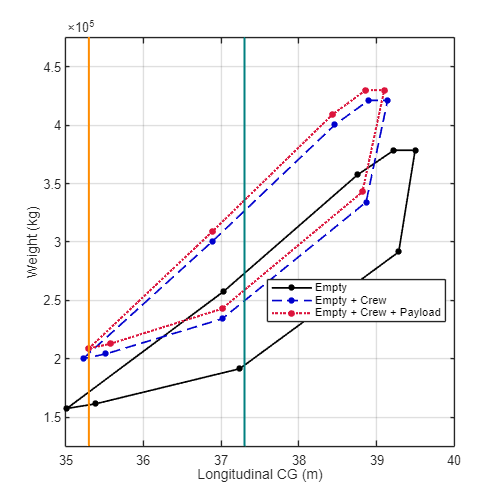


% Plot the C.G - envelope

figure(1)

clf;

plot(x_load_e, W_load_e, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c, W_load_c, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p, W_load_p, 'o:', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([35.3 35.3], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([37.3 37.3], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold off % Aft C.G. limit % Undefined

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload',...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

%xlim([35 37.5]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 500 500]); % show plot with larger size 

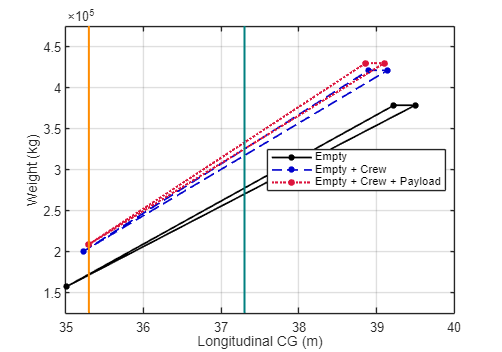

% Chose extreme case
x_load_e2 (1, 1) =  x_load_e (1, 1);
x_load_e2 (1, 2) =  x_load_e (1, 4);
x_load_e2 (1, 3) =  x_load_e (1, 5);
x_load_e2 (1, 4) =  x_load_e (1, 9);

W_load_e2 (1, 1) = W_load_e (1, 1);
W_load_e2 (1, 2) = W_load_e (1, 4);
W_load_e2 (1, 3) = W_load_e (1, 5);
W_load_e2 (1, 4) = W_load_e (1, 9);

x_load_c2 (1, 1) =  x_load_c (1, 1);
x_load_c2 (1, 2) =  x_load_c (1, 4);
x_load_c2 (1, 3) =  x_load_c (1, 5);
x_load_c2 (1, 4) =  x_load_c (1, 9);

W_load_c2 (1, 1) = W_load_c (1, 1);
W_load_c2 (1, 2) = W_load_c (1, 4);
W_load_c2 (1, 3) = W_load_c (1, 5);
W_load_c2 (1, 4) = W_load_c (1, 9);

x_load_p2 (1, 1) =  x_load_p (1, 1);
x_load_p2 (1, 2) =  x_load_p (1, 4);
x_load_p2 (1, 3) =  x_load_p (1, 5);
x_load_p2 (1, 4) =  x_load_p (1, 9);

W_load_p2 (1, 1) = W_load_p (1, 1);
W_load_p2 (1, 2) = W_load_p (1, 4);
W_load_p2 (1, 3) = W_load_p (1, 5);
W_load_p2 (1, 4) = W_load_p (1, 9);

% Plot the C.G - envelope

figure(2)

clf;

plot(x_load_e2, W_load_e2, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c2, W_load_c2, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p2, W_load_p2, 'o:', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([35.3 35.3], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([37.3 37.3], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold off % Aft C.G. limit % Undefined

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

%xlim([35 37.5]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 500 350]); % show plot with larger size

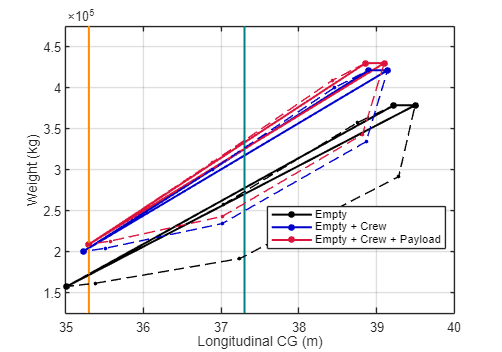

% Plot the C.G - envelope

figure(3)

clf;

plot(x_load_e2, W_load_e2, 'o-', 'Color',  [0/255 0/255 0/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c2, W_load_c2, 'o-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p2, W_load_p2, 'o-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.5, 'Markersize', 3.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold on % Empty + Crew + Payload
plot([35.3 35.3], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([37.3 37.3], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on % Aft C.G. limit % Undefined
plot(x_load_e, W_load_e, 'o--', 'Color',  [0/255 0/255 0/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [0/255 0/255 0/255])
hold on % Empty
plot(x_load_c, W_load_c, 'o--', 'Color', [0/255 0/255 205/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [0/255 0/255 205/255]);
hold on % Empty + Crew
plot(x_load_p, W_load_p, 'o--', 'Color', [220/255 20/255 60/255], 'LineWidth', 0.25, 'Markersize', 2.5 , 'MarkerFaceColor', [220/255 20/255 60/255]);
hold off % Empty + Crew + Payload

legend('Empty', 'Empty + Crew', 'Empty + Crew + Payload',...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)


xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

%xlim([35 37.5]);
ylim([1.25e5 4.75e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 500 350]); % show plot with larger size 

### **2.7 C.G - Mission Profile**

**Order of fuel burning:**

- Outer wing fuel tank - burned first to reduce wing bending moment

- Center (wing) fuel tank - to maintain a stable CG

- Inner wing fuel tank - burned later in the flight as fuel levels reduce

where trim tank is used dynamically to adjust CG as needed during flight

**Fuel fraction**

% This can be redone after design finish by fuel fraction codes
W_i = load('W_i.mat');
W_i = W_i.W_i;

Fuel useage in mission profile

W_f_mission = load('W_f.mat');
W_f_mission = W_f_mission.W_f;

W_f_use_mission (1, 1) = 0;
W_f_use_mission (1, 2) = W_0 - W_0 * W_i(1);
W_f_use_mission (1, 3) = W_0 - W_0 * W_i(1) * W_i(2);
W_f_use_mission (1, 4) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3);
W_f_use_mission (1, 5) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4);
W_f_use_mission (1, 6) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5);
W_f_use_mission (1, 7) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6);
W_f_use_mission (1, 8) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7);
W_f_use_mission (1, 9) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7) * W_i(8);
W_f_use_mission (1, 10) = W_0 - W_0 * W_i(1) * W_i(2) * W_i(3) * W_i(4) * W_i(5) * W_i(6) * W_i(7) * W_i(8) * W_i(9)

W_f_use_mission = 1.0e+05 *

         0    0.1290    0.1915    1.7538    1.7792    1.8035    1.8729    1.9122    1.9276    1.9465


**Without trim tank**

**0** Take-off Gross Weight

% Outer Wing Fuel Tank

x_f_mission_outer (1, 1) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre));

z_f_mission_outer (1, 1) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre));

W_f_mission_outer (1, 1) = W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre);

**0-1** Taxi & Takeoff

% Outer Wing Fuel Tank

x_f_mission_outer (1, 2) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)));

z_f_mission_outer (1, 2) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)));

W_f_mission_outer (1, 2) = W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2));

% Landing Gear Up

x_f_mission_outer (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)));

z_f_mission_outer (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2)));

W_f_mission_outer (1, 3) = W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 2));

**1-2** Climb and accelerate to cruise

% Outer Wing Fuel Tank

x_f_mission_outer (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 3)) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 3)));

z_f_mission_outer (1, 4) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 3)) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 3)));

W_f_mission_outer (1, 4) = W_e + W_crew + W_payload + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_use_mission (1, 3));

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Outer Wing Fuel Tank

x_f_mission_outer (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in + W_f_centre * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre)

x_f_mission_outer =    38.8670   38.6093   38.5991   38.4681   38.4309



z_f_mission_outer (1, 5) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in + W_f_centre * z_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_in + W_f_centre)

z_f_mission_outer =    -0.6972   -0.7343   -0.2692   -0.2809   -0.2843



W_f_mission_outer (1, 5) = W_e + W_crew + W_payload + W_f_in + W_f_centre

W_f_mission_outer = 1.0e+05 *

    4.2990    4.1700    4.1700    4.1075    4.0900




% Centre Wing Fuel Tank

x_f_mission_centre (1, 1) = x_f_mission_outer (1, 5); 

z_f_mission_centre (1, 1) = z_f_mission_outer (1, 5); 

W_f_mission_centre (1, 1) = W_f_mission_outer (1, 5);

x_f_mission_centre (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_in * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_in)

x_f_mission_centre =    38.4309   37.8573



z_f_mission_centre (1, 2) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_in * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_in)

z_f_mission_centre =    -0.2843   -0.3116



W_f_mission_centre (1, 2) = W_e + W_crew + W_payload + W_f_in

W_f_mission_centre = 1.0e+05 *

    4.0900    3.0886



% Inner Wing Fuel Tank

x_f_mission_in (1, 1) = x_f_mission_centre (1, 2);

z_f_mission_in (1, 1) = z_f_mission_centre (1, 2);

W_f_mission_in (1, 1) = W_f_mission_centre (1, 2);

x_f_mission_in (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 4)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 4)));

z_f_mission_in (1, 2) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 4)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 4))); 

W_f_mission_in (1, 2) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 4));

**3-4** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

z_f_mission_in (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

W_f_mission_in (1, 3) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5));

% Landing Gear down

x_f_mission_in (1, 4) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

z_f_mission_in (1, 4) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

W_f_mission_in (1, 4) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5));

% Landing Gear Up

x_f_mission_in (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5)));

z_f_mission_in (1, 5) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5))); 

W_f_mission_in (1, 5) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 5));

**4-5** Missed approach, followed by clmb and accelerate to alternate

% Inner Wing Fuel Tank

x_f_mission_in (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 6)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 6)));

z_f_mission_in (1, 6) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 6)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 6)));

W_f_mission_in (1, 6) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 6));

**5-6** Cruise to alternate destination 370 km away

% Inner Wing Fuel Tank

x_f_mission_in (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 7)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 7))); 

z_f_mission_in (1, 7) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 7)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 7)));

W_f_mission_in (1, 7) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 7));

**6-7** Loiter at 5000 ft for 45 minutes

% Inner Wing Fuel Tank

x_f_mission_in (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 8)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 8)));

z_f_mission_in (1, 8) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 8)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 8)));

W_f_mission_in (1, 8) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 8));

**7-8** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in (1, 9) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9)));

z_f_mission_in (1, 9) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 9)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9)));

W_f_mission_in (1, 9) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9));

% Landing Gear Up

x_f_mission_in (1, 10) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9)));

z_f_mission_in (1, 10) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 9)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9)));

W_f_mission_in (1, 10) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 9));

**8-9** Landing & Taxi

% Inner Wing Fuel Tank

x_f_mission_in (1, 11) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + (W_f - W_f_use_mission (1, 10)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 10))) 

x_f_mission_in =    37.8573   36.7167   36.6512   36.6681   36.6512   36.5874   36.3984   36.2862   36.2415   36.2594   36.2035


z_f_mission_in (1, 11) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + (W_f - W_f_use_mission (1, 10)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 10)))

z_f_mission_in =    -0.3116   -0.3781   -0.3819   -1.1515   -0.3819   -0.3857   -0.3967   -0.4032   -0.4058   -1.2236   -1.2334



W_f_mission_in (1, 11) = W_e + W_crew + W_payload + (W_f - W_f_use_mission (1, 10))

W_f_mission_in = 1.0e+05 *

    3.0886    2.5452    2.5198    2.5198    2.5198    2.4955    2.4261    2.3868    2.3714    2.3714    2.3525


**With trim tank**

**0** Take-off Gross Weight

% Outer Wing Fuel Tank

x_f_mission_outer2 (1, 1) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim));

z_f_mission_outer2 (1, 1) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim));

W_f_mission_outer2 (1, 1) = W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim);

**0-1** Taxi & Takeoff

% Outer Wing Fuel Tank

x_f_mission_outer2 (1, 2) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)));

z_f_mission_outer2 (1, 2) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)));

W_f_mission_outer2 (1, 2) = W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2));

% Landing Gear Up

x_f_mission_outer2 (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + W_f_centre * x_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)) * x_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)));

z_f_mission_outer2 (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in + W_f_centre * z_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)) * z_f_out) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2)));

W_f_mission_outer2 (1, 3) = W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre + (W_f - W_f_in - W_f_centre - W_f_trim - W_f_use_mission (1, 2));

**1-2** Climb and accelerate to cruise

% Outer Wing Fuel Tank

x_f_mission_outer2 (1, 4) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + W_f_centre * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre)

x_f_mission_outer2 =    38.8931   38.6362   38.6259   38.5429



z_f_mission_outer2 (1, 4) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in + W_f_centre * z_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre)

z_f_mission_outer2 =    -0.7112   -0.7486   -0.2836   -0.2912



W_f_mission_outer2 (1, 4) = W_e + W_crew + W_payload + W_f_trim + W_f_in + W_f_centre

W_f_mission_outer2 = 1.0e+05 *

    4.2990    4.1700    4.1700    4.1300



% Centre Wing Fuel Tank

x_f_mission_centre2 (1, 1) = x_f_mission_outer2 (1, 4);

z_f_mission_centre2 (1, 1) = z_f_mission_outer2 (1, 4); 

W_f_mission_centre2 (1, 1) = W_f_mission_outer2 (1, 4);

x_f_mission_centre2 (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in + ...
    (W_f - W_f_in - W_f_trim - W_f_use_mission (1, 3)) * x_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_in - W_f_trim - W_f_use_mission (1, 3)));

z_f_mission_centre2 (1, 2) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in + ...
    (W_f - W_f_in - W_f_trim - W_f_use_mission (1, 3)) * z_f_centre) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_in - W_f_trim - W_f_use_mission (1, 3)));

W_f_mission_centre2 (1, 2) = W_e + W_crew + W_payload + W_f_trim + W_f_in + (W_f - W_f_in - W_f_trim - W_f_use_mission (1, 3));

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

% Centre Wing Fuel Tank

x_f_mission_centre2 (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + W_f_in * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in)

x_f_mission_centre2 =    38.5429   38.5338   38.0125



z_f_mission_centre2 (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + W_f_in * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + W_f_in)

z_f_mission_centre2 =    -0.2912   -0.2917   -0.3204



W_f_mission_centre2 (1, 3) = W_e + W_crew + W_payload + W_f_trim + W_f_in

W_f_mission_centre2 = 1.0e+05 *

    4.1300    4.1075    3.1286




% Inner Wing Fuel Tank

x_f_mission_in2 (1, 1) = x_f_mission_centre2 (1, 3);

z_f_mission_in2 (1, 1) = z_f_mission_centre2 (1, 3);

W_f_mission_in2 (1, 1) = W_f_mission_centre2 (1, 3);

x_f_mission_in2 (1, 2) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4))); 

z_f_mission_in2 (1, 2) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4))); 

W_f_mission_in2 (1, 2) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 4));

**3-4** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 3) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

z_f_mission_in2 (1, 3) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

W_f_mission_in2 (1, 3) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5));

% Landing Gear Down

x_f_mission_in2 (1, 4) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

z_f_mission_in2 (1, 4) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

W_f_mission_in2 (1, 4) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5));

% Landing Gear Up

x_f_mission_in2 (1, 5) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

z_f_mission_in2 (1, 5) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5))); 

W_f_mission_in2 (1, 5) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 5));

**4-5** Missed approach, followed by clmb and accelerate to alternate

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 6) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6)));

z_f_mission_in2 (1, 6) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6))); 

W_f_mission_in2 (1, 6) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 6));

**5-6** Cruise to alternate destination 370 km away

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 7) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7))); 

z_f_mission_in2 (1, 7) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7))); 

W_f_mission_in2 (1, 7) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 7));

**6-7** Loiter at 5000 ft for 45 minutes

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 8) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8)));

z_f_mission_in2 (1, 8) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8))); 

W_f_mission_in2 (1, 8) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 8));

**7-8** Descent to land

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 9) = (W_e * x_e + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)));

z_f_mission_in2 (1, 9) = (W_e * z_e + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9))); 

W_f_mission_in2 (1, 9) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9));

% Landing Gear Down

x_f_mission_in2 (1, 10) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)));

z_f_mission_in2 (1, 10) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9))); 

W_f_mission_in2 (1, 10) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 9));

**8-9** Landing & Taxi

% Inner Wing Fuel Tank

x_f_mission_in2 (1, 11) = (W_e * x_e_down + W_crew * x_crew + W_payload * x_payload + W_f_trim * x_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10)) * x_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10))) 

x_f_mission_in2 =    38.0125   36.8235   36.7591   36.7760   36.7591   36.6964   36.5105   36.4002   36.3562   36.3741   36.3191



z_f_mission_in2 (1, 11) = (W_e * z_e_down + W_crew * z_crew + W_payload * z_payload + W_f_trim * z_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10)) * z_f_in) ./ ...
    (W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10))); 

W_f_mission_in2 (1, 11) = W_e + W_crew + W_payload + W_f_trim + (W_f - W_f_trim - W_f_use_mission (1, 10))

W_f_mission_in2 = 1.0e+05 *

    3.1286    2.5452    2.5198    2.5198    2.5198    2.4955    2.4261    2.3868    2.3714    2.3714    2.3525


**Plot the C.G - mission profile**

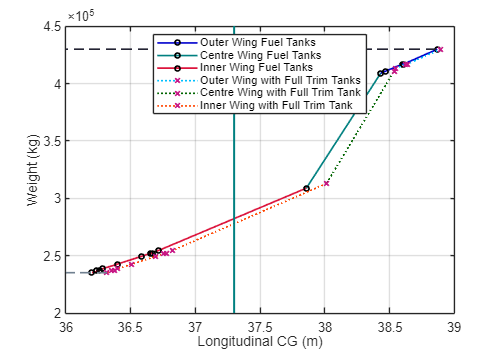

figure(4)

clf;

plot(x_f_mission_outer, W_f_mission_outer, 'o-', 'Color',  [0/255 0/255 205/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Outer Wing Fuel Tank without trim tank
plot(x_f_mission_centre, W_f_mission_centre, 'o-', 'Color',  [0/255 128/255 128/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255])
hold on % Centre Wing Fuel Tank without trim tank
plot(x_f_mission_in, W_f_mission_in, 'o-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25, 'Markersize', 3.75 , 'MarkerEdgeColor', [0/255 0/255 0/255]);
hold on % Inner Wing Fuel Tank without trim tank
plot(x_f_mission_outer2, W_f_mission_outer2, 'x:', 'Color',  [0/255 191/255 255/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [199/255 21/255 133/255])
hold on % Outer Wing Fuel Tank with trim tank
plot(x_f_mission_centre2, W_f_mission_centre2, 'x:', 'Color',  [0/255 100/255 0/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [199/255 21/255 133/255])
hold on % Centre Wing Fuel Tank with trim tank
plot(x_f_mission_in2, W_f_mission_in2, 'x:', 'Color', [255/255 69/255 0/255], 'LineWidth', 1.25, 'Markersize', 5 , 'MarkerEdgeColor', [199/255 21/255 133/255]);
hold on % Inner Wing Fuel Tank without trim tank
plot([35.3 35.3], [0 5e5], '-', 'Color', [255/255 140/255 0/255], 'LineWidth', 1.5);
hold on % Forward C.G. limit % Undefined
plot([37.3 37.3], [0 5e5], '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.5);
hold on % Aft C.G. limit % Undefined
plot([0 x_f_mission_outer2(1)], [W_f_mission_outer(1) W_f_mission_outer(1)], '--', 'Color', [35/255 35/255 51/255], 'LineWidth', 1.25);
hold on % W_0
plot([0 x_f_mission_in2(end)], [W_f_mission_in(end) W_f_mission_in(end)], '--', 'Color', [112/255 128/255 144/255], 'LineWidth', 1.25);
hold on % W_land % Undefined

% Hide legend for final version
legend('Outer Wing Fuel Tanks', 'Centre Wing Fuel Tanks', 'Inner Wing Fuel Tanks', ...
    'Outer Wing with Full Trim Tanks', 'Centre Wing with Full Trim Tank', 'Inner Wing with Full Trim Tank', ...
       'Location', 'best', 'NumColumns', 1, FontSize = 8.5)

xlabel('Longitudinal CG (m)');
ylabel('Weight (kg)');

set(gca, 'FontSize', 9.5) % set the fontsize of the axis

xlim([36 39]);
ylim([2e5 4.5e5]);

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 500 350]); % show plot with larger size

**Store the value**

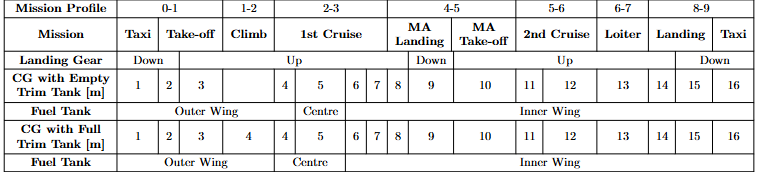

% x_f_empty = [x_f_mission_outer, x_f_mission_centre(2 : end), x_f_mission_in(2 : end)]
x_f_empty = [x_f_mission_outer(1 : end - 1), x_f_mission_centre(1 : end - 1), x_f_mission_in(1 : end)]

x_f_empty =    38.8670   38.6093   38.5991   38.4681   38.4309   37.8573   36.7167   36.6512   36.6681   36.6512   36.5874   36.3984   36.2862   36.2415   36.2594   36.2035


% x_f_full = [x_f_mission_outer2, x_f_mission_centre2(2 : end), x_f_mission_in2(2 : end)]
x_f_full= [x_f_mission_outer2(1 : end - 1), x_f_mission_centre2(1 : end - 1), x_f_mission_in2(1 : end)]

x_f_full =    38.8931   38.6362   38.6259   38.5429   38.5338   38.0125   36.8235   36.7591   36.7760   36.7591   36.6964   36.5105   36.4002   36.3562   36.3741   36.3191


z_f_empty = [z_f_mission_outer(1 : end - 1), z_f_mission_centre(1 : end - 1), z_f_mission_in(1 : end)]

z_f_empty =    -0.6972   -0.7343   -0.2692   -0.2809   -0.2843   -0.3116   -0.3781   -0.3819   -1.1515   -0.3819   -0.3857   -0.3967   -0.4032   -0.4058   -1.2236   -1.2334


z_f_full = [z_f_mission_outer2(1 : end - 1), z_f_mission_centre2(1 : end - 1), z_f_mission_in2(1 : end)]

z_f_full =    -0.7112   -0.7486   -0.2836   -0.2912   -0.2917   -0.3204   -0.3938   -0.3978   -1.1674   -0.3978   -0.4017   -0.4132   -0.4200   -0.4227   -1.2404   -1.2504



W_mission = [W_f_mission_outer(1 : end - 1), W_f_mission_centre(1 : end - 1), W_f_mission_in(1 : end)]

W_mission = 1.0e+05 *

    4.2990    4.1700    4.1700    4.1075    4.0900    3.0886    2.5452    2.5198    2.5198    2.5198    2.4955    2.4261    2.3868    2.3714    2.3714    2.3525
